clear all; close all; clc


Matrix recovery—— one matrix



% Load the dataset
load('Sparse_Low_Rank_dataset.mat'); %  1000 matrices

% Select the k-th sample for processing
k = 150; 
H_true = reshape(H(:,:,k), [32, 32]); % Extract a 32x32 matrix
rank_H_true=rank(H_true);
X_true= fft2(H_true);
% sampling mask M (randomly select 10% of the elements)
N = 32;
p = 0.1; % Sampling ratio
tol = 1e-7;  
M = rand(N, N) < p; % a random 0-1 sampling matrix
y = M .* H_true; 

%Set parameters
alpha = 1e-4;  % Nuclear norm regularization weight (controls low-rank property)
beta = 0.11;  % L1 regularization weight in the DFT domain (controls sparsity)
eta = 1.2;   % Learning rate
max_iter = 100; % Number of iterations

% Initialize variables

phi = y;

% 6.   Successive Proximal Gradient Descent  
loss_history = [];
for i = 1:max_iter
    % Gradient descent 
    grad = M .* (phi - y);                 
    phi1 = phi - eta * grad;            

    % Frequency domain sparsity  
    X1 = fft2(phi1);                     
    X2 = X1 .* max(1 - (eta * beta) ./ abs(X1), 0);  % Soft-thresholding
    phi2 = ifft2(X2);                   

    % Low-rank nuclear norm 
    [U, S1, V] = svd(phi2, 'econ');
    S2 = max(S1 - eta * alpha, 0);       % Soft-thresholding
    phi3 = U * S2 * V';

    % Compute loss 
    loss = norm(M .* (phi3 - y), 'fro')^2 + ...
           alpha * sum(diag(S2)) + ...
           beta * sum(abs(X2(:)));
    loss_history(end+1) = loss;

    % ----- Check convergence -----
    if i > 1 && abs(loss_history(end) - loss_history(end-1)) < tol
        fprintf('Converged at iteration %d, Loss: %.4e\n', i, loss);
        break;
    end

    % ----- Update -----
    phi = phi3;
end

rank(phi3);

%frobenius_error = norm(H_true - phi3, 'fro') % Frobenius norm error
% mse_error = mean((H_true(:) - phi3(:)).^2); % Mean squared error
% relative_error = norm(H_true - phi3, 'fro') / norm(H_true, 'fro'); % Normalized error
err = 1e0 * norm((H_true - phi3), 'fro')^2;
perc = err / norm((H_true), 'fro')^2

perc = 0.0418

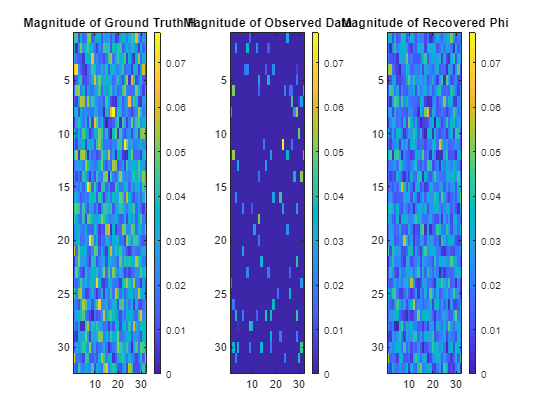



figure;

% Ignore NaN and Inf values
vmin = min([abs(H_true(:)); abs(y(:)); abs(phi3(:))], [], 'omitnan');
vmax = max([abs(H_true(:)); abs(y(:)); abs(phi3(:))], [], 'omitnan');


% Display results (using the same color range)
figure;
subplot(1,3,1); imagesc(abs(H_true)); title('Magnitude of Ground Truth H'); colorbar;
clim([vmin vmax]); 

subplot(1,3,2); imagesc(abs(y)); title('Magnitude of Observed Data'); colorbar;
clim([vmin vmax]);

subplot(1,3,3); imagesc(abs(phi)); title('Magnitude of Recovered Phi'); colorbar;
clim([vmin vmax]); 

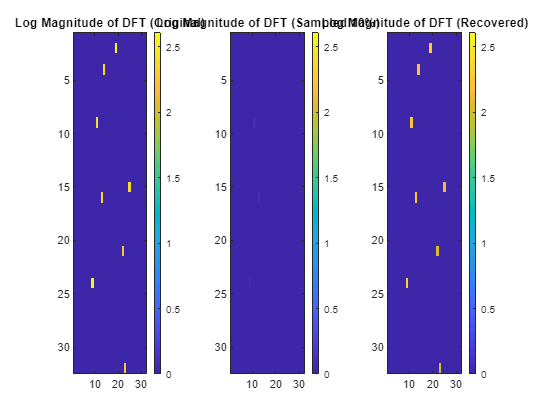


DFT_first = fftshift(fft2(H_true));
DFT_sampled = fftshift(fft2(y));
DFT_hat = fftshift(fft2(phi));

eps_val = 1e-8;
log_mag_first = log(abs(DFT_first) + eps_val);
log_mag_sampled = log(abs(DFT_sampled) + eps_val);
log_mag_hat = log(abs(DFT_hat) + eps_val);

% color scale unifying
vmax_dft = max([max(log_mag_first(:)), max(log_mag_sampled(:)), max(log_mag_hat(:))]);

figure;
subplot(1,3,1);
imagesc(log_mag_first, [0, vmax_dft]);
colorbar;
title('Log Magnitude of DFT (Original)');
m = p*100;
subplot(1,3,2);
imagesc(log_mag_sampled, [0, vmax_dft]);
colorbar;
title(['Log Magnitude of DFT (Sampled ', num2str(m), '%)']);

subplot(1,3,3);
imagesc(log_mag_hat, [0, vmax_dft]);
colorbar;
title('Log Magnitude of DFT (Recovered)');

Matrix recovery—— 1000 matrices

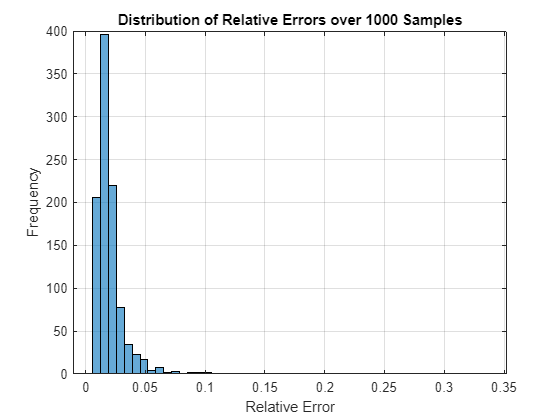


load('Sparse_Low_Rank_dataset.mat'); %  1000 samples 
num_samples = size(H, 3); 
N = 32;
p = 0.1; % Sampling ratio
tol = 1e-7;

% Set hyperparameters
alpha = 1e-4;  % Nuclear norm regularization weight
beta = 0.11;   % L1 regularization weight in DFT domain
eta = 1.2;     % Learning rate
max_iter = 150;

% Array to store relative errors
perc_list = zeros(num_samples, 1);

for k = 1:num_samples
    H_true = reshape(H(:,:,k), [N, N]);
    X_true = fft2(H_true);

    % Generate random mask
    M = rand(N, N) < p;
    y = M .* H_true;

    % Initialize
    phi = y;
    loss_history = [];

    for i = 1:max_iter
        % Gradient step (data fidelity)
        grad = M .* (phi - y);
        phi1 = phi - eta * grad;

        % L1 sparsity in frequency domain
        X1 = fft2(phi1);
        X2 = X1 .* max(1 - (eta * beta) ./ abs(X1), 0);  % Soft-thresholding
        phi2 = ifft2(X2);

        % Low-rank via nuclear norm
        [U, S1, V] = svd(phi2, 'econ');
        S2 = max(S1 - eta * alpha, 0);
        phi3 = U * S2 * V';

        % Loss 
        loss = norm(M .* (phi3 - y), 'fro')^2 + ...
               alpha * sum(diag(S2)) + ...
               beta * sum(abs(X2(:)));
        loss_history(end+1) = loss;

        if i > 1 && abs(loss_history(end) - loss_history(end-1)) < tol
            break;
        end

        phi = phi3;
    end

    % Compute relative Frobenius error
    err = norm(H_true - phi3, 'fro')^2;
    perc = err / norm(H_true, 'fro')^2;
    perc_list(k) = perc;
end

% Plot histogram of relative errors
figure;
histogram(perc_list, 50);  % 50 bins
xlabel('Relative Error');
ylabel('Frequency');
title('Distribution of Relative Errors over 1000 Samples');
grid on;

Plot for report and presentation

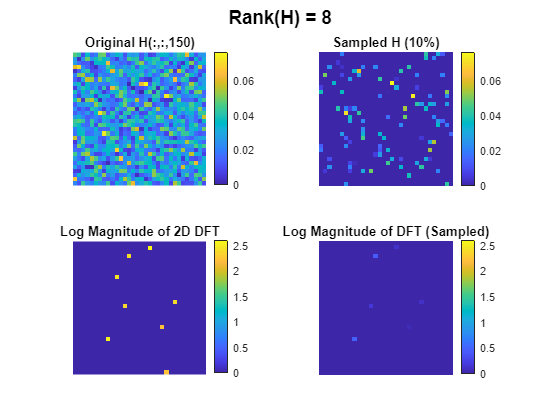

clear all; close all; clc

% Load data
data = load('Sparse_Low_Rank_dataset.mat');
H = data.H;  
H_first = H(:,:,150);  % Take the 150th frame
[nx, ny] = size(H_first);

% Compute rank
r = rank(H_first);

% DFT of original matrix
DFT_H = fftshift(fft2(H_first));
log_mag = log(abs(DFT_H) + 1e-8);  % Avoid log(0)

% Construct sampling mask
m = 10;  % Sampling ratio (in %)
num_samples = round((m / 100) * nx * ny);
linear_indices = randperm(nx * ny, num_samples); 
sampling_mask = zeros(nx, ny);
sampling_mask(linear_indices) = 1;

% Sampled matrix and its DFT
H_sampled = H_first .* sampling_mask;
DFT_sampled = fftshift(fft2(H_sampled));
log_mag_sampled = log(abs(DFT_sampled) + 1e-8);

% Unified color scale 

% Spatial domain (top row)
vmax_abs = max([max(abs(H_first(:))), max(abs(H_sampled(:)))]);

% Frequency domain (bottom row)
vmax_dft = max([max(log_mag(:)), max(log_mag_sampled(:))]);

% Plotting 
figure;

% Original matrix
subplot(2,2,1);
imagesc(abs(H_first), [0, vmax_abs]);
axis image off;
colorbar;
title('Original H(:,:,150)');

% Original DFT
subplot(2,2,3);
imagesc(log_mag, [0, vmax_dft]);
axis image off;
colorbar;
title('Log Magnitude of 2D DFT');

% Sampled matrix
subplot(2,2,2);
imagesc(abs(H_sampled), [0, vmax_abs]);
axis image off;
colorbar;
title(['Sampled H (', num2str(m), '%)']);

% DFT of sampled matrix
subplot(2,2,4);
imagesc(log_mag_sampled, [0, vmax_dft]);
axis image off;
colorbar;
title('Log Magnitude of DFT (Sampled)');

% Super title
sgtitle(['Rank(H) = ', num2str(r)], 'FontSize', 14, 'FontWeight', 'bold');